# Assignment 1

February 3, 2024

Christopher Maxwell

Z23637240

## Image Import

A. Read an image into a workspace variable.

URL = "https://bpb-us-e1.wpmucdn.com/sites.psu.edu/dist/5/8695/files/2014/02/alaska1.jpg";
A   = imread(URL);

[Click here](https://sites.psu.edu/passiondgeary/2014/02/06%20laska/) to view image source.

## Image Display

B. Display the image.

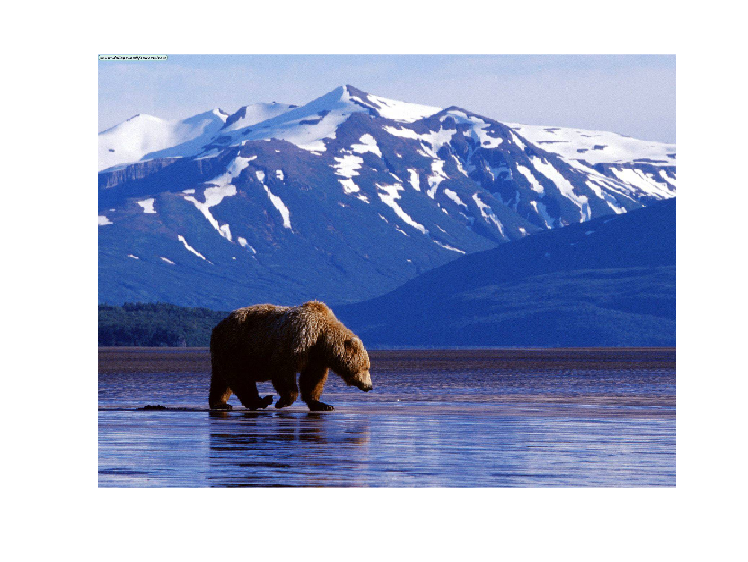

imshow(A)


disp('Image source: https://sites.psu.edu/passiondgeary/2014/02/06/alaska/')

Image source: https://sites.psu.edu/passiondgeary/2014/02/06/alaska/


## Image Processing

C. Apply an image processing filter/effect.

### Brighten Image

br = imlocalbrighten(A);

### Convert to Grayscale

gs = im2gray(A);

### Adjust Grayscale Image Contrast

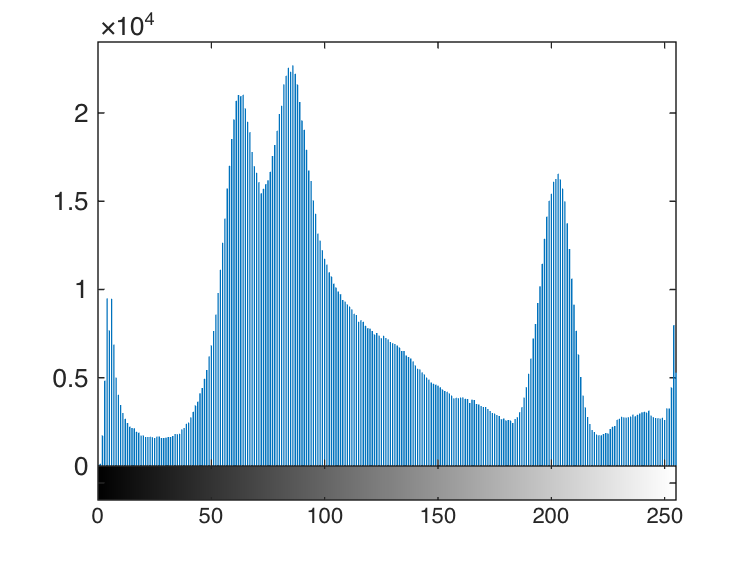

imhist(gs)

gsAdj = imadjust(gs);

Apply Bottom Hat Transform

SE  = strel("disk",8);
BHT = imbothat(gs,SE);

## Processed Image Display

D. Display processed images.

disp('Brightened image:')

Brightened image:


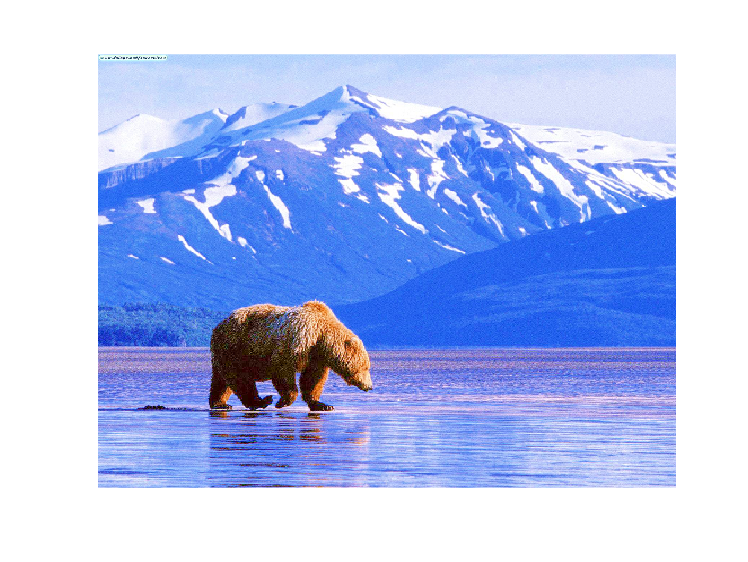

imshow(br)


disp('Grayscale image:')

Grayscale image:


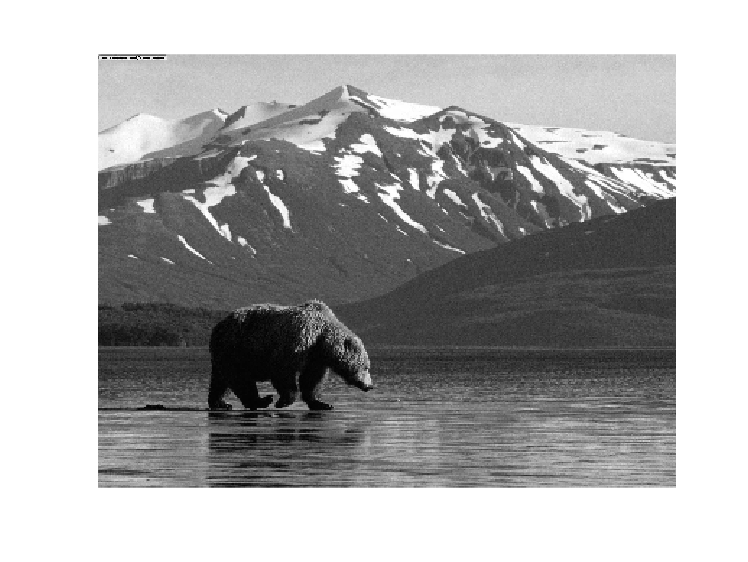

imshow(gs)


disp('Comparison:')

Comparison:


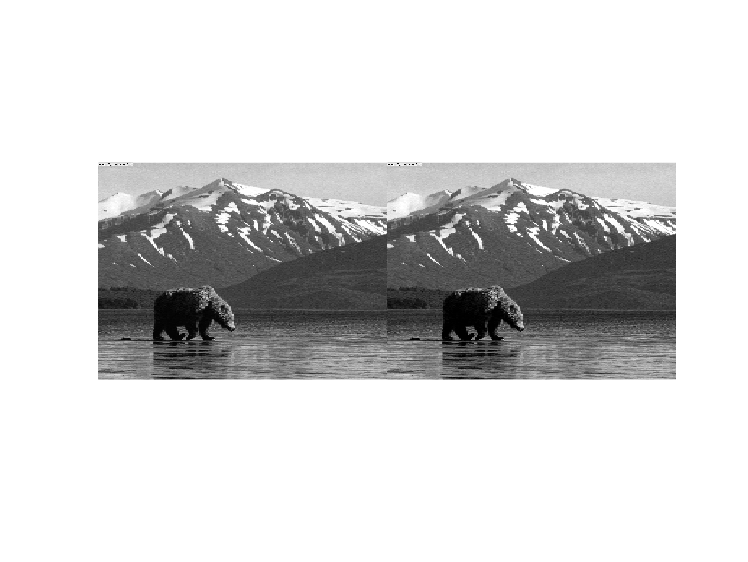

imshowpair(gs,gsAdj,"montage")


disp('Bottom Hat Transform')

Bottom Hat Transform


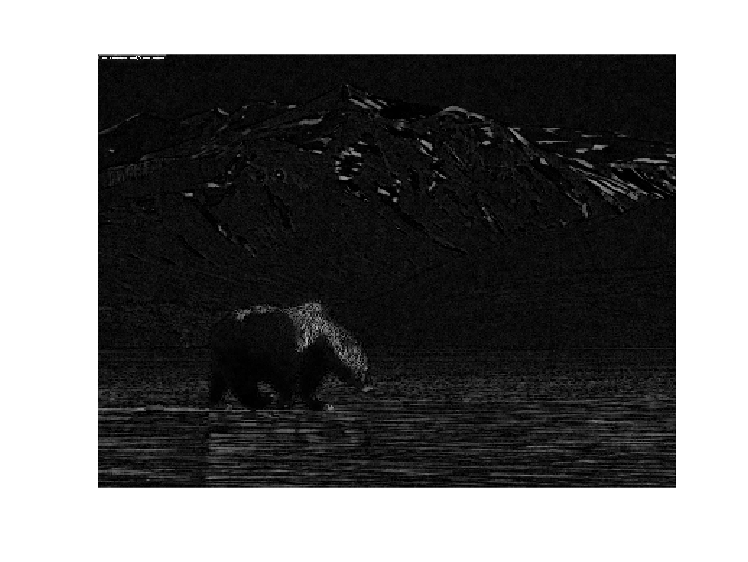

imshow(BHT)

## Save Image

E. Save the resulting image/s to a .png file.

imwrite(br,"img_br.png");
imwrite(gs,"img_gs.png");
imwrite(BHT,"img_BHT.png");